clearvars;

Global Constant Definitions

ConstGlb.whatTrs = ["turnon", "turnoff"];
ConstGlb.whatCh = ["Id", "Vds", "Vgs"];
ConstGlb.namePart = dictionary( ...
    ["Ron" "Roff" "Pulse" "Vds" "Vgson" "Vgsoff" "trs" "id"], ...
    [ 2     4      6       8     10      12       13    16]);
ConstGlb.testInductance = 1.0;  % [mH]
ConstGlb.minmax = dictionary( ...
    ["Ronmin"   "Ronmax"    "Roffmin"   "Roffmax"   "Idmin"     "Idmax" ...
     "Vdsmin"   "Vdsmax"    "Vgsonmin"  "Vgsonmax"  "Vgsoffmin" "Vgsoffmax"], ...
    [0          30          0           30          0           200 ...
     200        600         10          20          -5          0]);
ConstGlb.predVars = ["Vgs" "Ron_test" "Roff_test" "Id_test" "Vds_test" "Vgson_test" "Vgsoff_test"];

Make a list of the data

dataPath = "../Data/Wavelet_Result_transient/TimeDomain";
for whatTrs = ConstGlb.whatTrs
    dataFileList.(whatTrs) = dir(dataPath + "/" + whatTrs);
    [dataFileNum.(whatTrs), ~] = size(dataFileList.(whatTrs));
end
clear whatTrs

Import the data

dataImportTic = tic();
clear data
for whatTrs = ConstGlb.whatTrs
    for k = 3:dataFileNum.(whatTrs) % The first and the second file in the list are "." and ".."
        dataNum = k-2;
        fileName = dataFileList.(whatTrs)(k).name;
        filePath = dataPath + "/" + whatTrs + "/" + fileName;
        data.(whatTrs){dataNum, 1} = readtable(filePath);
        nameParts = split(fileName, "_");
        dict = ConstGlb.namePart;
        Ron = string(nameParts{dict("Ron")});
        Ron = double(Ron)/10;      % [Ohm]
        Roff = string(nameParts{dict("Roff")});
        Roff = double(Roff)/10;    % [Ohm]
        Pulse = string(nameParts{dict("Pulse")});
        Pulse = double(Pulse);     % [us]
        Vds = string(nameParts{dict("Vds")});
        Vds = double(Vds);         % [V]
        Vgson = string(nameParts{dict("Vgson")});
        Vgson = double(Vgson);     % [V]
        Vgsoff = string(nameParts{dict("Vgsoff")});
        Vgsoff = -double(Vgsoff);   % [V]
        Id = Vds/(ConstGlb.testInductance*1e-3) * (Pulse*1e-6); 
        data.(whatTrs){dataNum, 2} = table(Ron, Roff, Id, Vds, Vgson, Vgsoff);
    end
end
clear dict Ron Roff Pulse Vds Vgson Vgsoff Id
clear whatTrs k filePath fileName dataNum nameParts
fprintf("Data Import Time: %02d:%02d:%02.3f\n", sec2time(toc(dataImportTic)));

Data Import Time: 00:00:19.235


clear dataImportTic

Data parsing for the train

for whatTrs = ConstGlb.whatTrs
    dataNum = length(data.(whatTrs));
    data_parsed.(whatTrs) = cell(dataNum, 1);
    for k = 1:dataNum
        data_parsed.(whatTrs){k,1} = table();
        for whatCh = ConstGlb.whatCh
            data_parsed.(whatTrs){k,1}.(whatCh) = data.(whatTrs){k,1}.(whatCh);
        end
        clear whatCh

        tbl = data.(whatTrs){k,2};

        % Normalization by target experiment values
        data_parsed.(whatTrs){k,1}.Id = data_parsed.(whatTrs){k,1}.Id/tbl.Id;
        data_parsed.(whatTrs){k,1}.Vds = data_parsed.(whatTrs){k,1}.Vds/tbl.Vds;
        data_parsed.(whatTrs){k,1}.Vgs = ...
            (data_parsed.(whatTrs){k,1}.Vgs - tbl.Vgsoff)/(tbl.Vgson - tbl.Vgsoff);
        minmax = ConstGlb.minmax;
        for vars = string(tbl.Properties.VariableNames)
           data_parsed.(whatTrs){k,1}.(vars+"_test") = repmat(...
               (data.(whatTrs){k,2}.(vars) - minmax(vars+"min"))/(minmax(vars+"max") - minmax(vars+"min")), ...
                size(data_parsed.(whatTrs){k,1}, 1), 1);
        end
        clear minmax vars
        clear tbl
    end
    clear k
end
clear whatTrs

Condition for train

trainTrs = "turnon";

allVars = string(data_parsed.turnoff{1}.Properties.VariableNames);
predVars = ConstGlb.predVars

predVars = 1×7 string 배열
    "Vgs"    "Ron_test"    "Roff_test"    "Id_test"    "Vds_test"    "Vgson_test"    "Vgsoff_test"


respVars = allVars(~matches(allVars, predVars))

respVars = 1×2 string 배열
    "Id"    "Vds"


whatTrs = trainTrs;
dataNum = length(data_parsed.(whatTrs))

dataNum = 456

clear predictors response
predictors = cell(dataNum, 1);
response = cell(dataNum, 1);

for k = 1:dataNum
    predictors{k} = table();
    response{k} = table();
    
    for vars = predVars
        predictors{k}.(vars) = data_parsed.(whatTrs){k}.(vars);
    end
    for vars = respVars
        response{k}.(vars) = data_parsed.(whatTrs){k}.(vars);
    end
    predictors{k} = table2array(predictors{k})';
    predictors{k} = predictors{k}(:,1:end-1);
    response{k} = table2array(response{k})';
    response{k} = response{k}(:, 2:end);
    clear vars
end
clear k
clear allVars predVars respVars whatTrs

whos("predictors", "response")

  Name              Size                Bytes  Class    Attributes

  predictors      456x1             319221888  cell               
  response        456x1              91240128  cell               



rng(917)
rand_indices = randperm(dataNum);

validationRatio = 0.3;
numVal = floor(validationRatio*dataNum)

numVal = 136

numTrain = dataNum - numVal

numTrain = 320

idxTrain = rand_indices(1:numTrain);
idxVal = rand_indices(numTrain+1:end);

XTrain = predictors(idxTrain);
YTrain = response(idxTrain);

XVal = predictors(idxVal);
YVal = response(idxVal);

LSTM layer architecture

Hyperparameters

miniBatchSize = 64;
validationFreq = miniBatchSize/8;
maxEpochs = 10000;

Architecture parameters

numHiddenUnits1 = 300;
numHiddenUnits2 = 150;
widthHiddenFcl1 = 200;
widthHiddenFcl2 = 120;
dropoutLstm = 0.3;
dropoutFcl = 0.5;

Layer construction

numFeatures = size(predictors{1},1)

numFeatures = 7

numResponses = size(response{1}, 1)

numResponses = 2

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits1,'OutputMode','sequence')
    dropoutLayer(dropoutLstm)
    lstmLayer(numHiddenUnits1,'OutputMode','sequence')
    dropoutLayer(dropoutLstm)
    fullyConnectedLayer(widthHiddenFcl1)
    reluLayer()
    dropoutLayer(dropoutFcl)
    fullyConnectedLayer(widthHiddenFcl2)
    reluLayer()
    dropoutLayer(dropoutFcl)
    fullyConnectedLayer(numResponses) % to predict Id and Vds
    regressionLayer];

Training option

options = trainingOptions('adam', ...
    'MaxEpochs',maxEpochs, ...
    'L2Regularization', 0.0001, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.001, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress', ...
    'Shuffle','never', ...
    'MiniBatchSize', miniBatchSize, ...
    'ExecutionEnvironment', 'gpu', ...
    'ValidationData', {XVal, YVal}, ...
    'ValidationFrequency', validationFreq, ...
    'OutputNetwork', 'best-validation-loss');

Check the model

analyzeNetwork(layers)

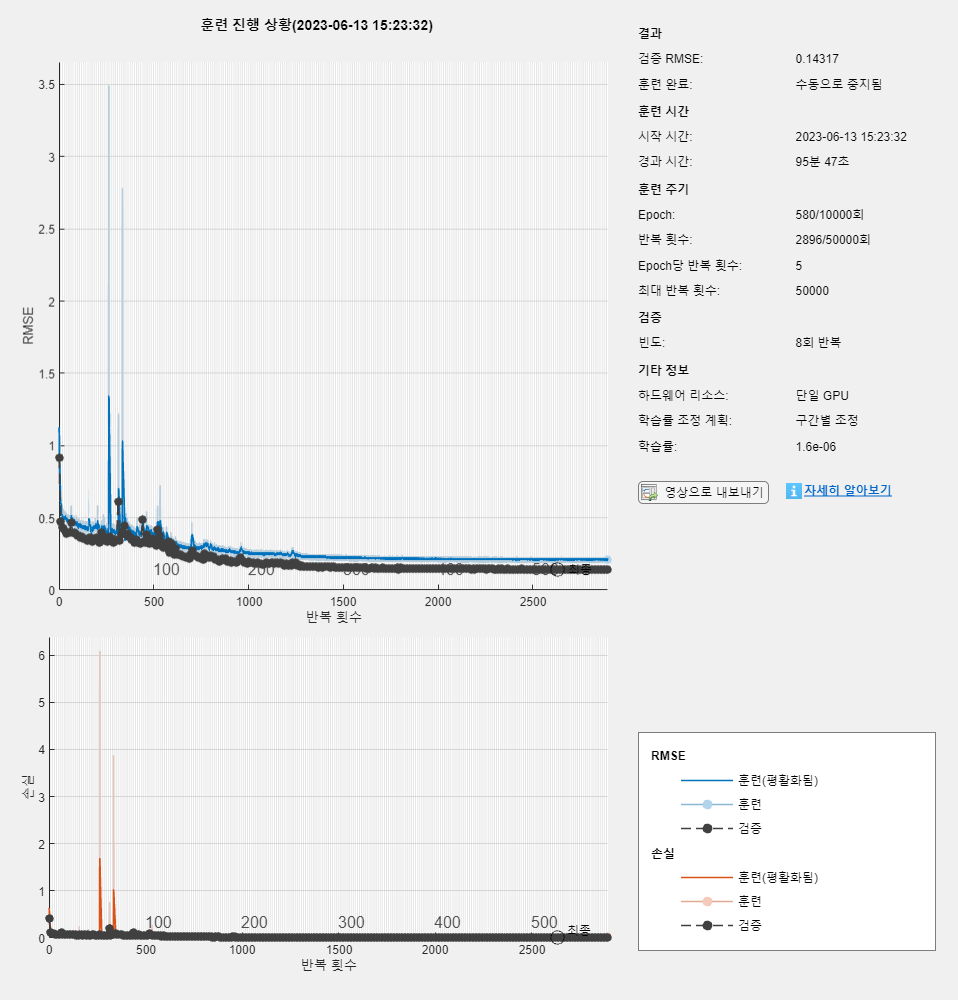

net = trainNetwork(XTrain, YTrain, layers, options);

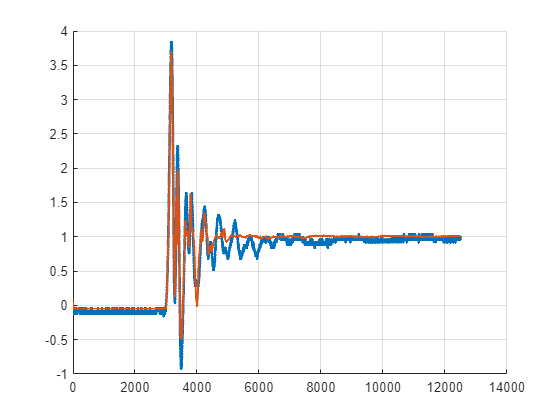

testNum = 87;

YPred = predict(net, XVal{testNum});

figure();
hold on;
plot(YVal{testNum}(1,:), LineWidth=2.0)
plot(YPred(1,:), LineWidth=1.5)
grid on;
hold off;

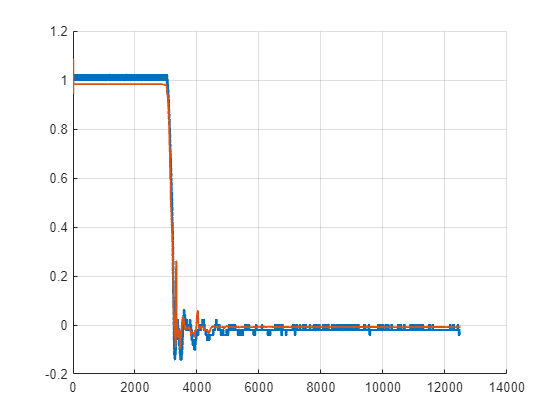

figure();
hold on;
plot(YVal{testNum}(2,:), LineWidth=2.0)
plot(YPred(2,:), LineWidth=1.5)
grid on;
hold off;